% Step 1: First we must define the step size, (h)*******
h = (1/64);

% Step 2: Next we must define the approximation domain (x)*******
% a = Beginning x domain value
a = 0;
% b = Ending x domain value
b = 20;

% Step 3: Then we must define the number of iterations
n = (b-a)/h;

% Step 4: Then we define the array for the x values for the purpose of the table ouput
% Where n is the number of rows
x = linspace(a,b,n)';

% Step 5a: Now we must define the array for the y values (Array of Zeroes)
% It is defined as a array with n number of rows and 1 column
y = zeros(n,1);

% Step 5b: Now we must define the array for the q values
% The q array represents the analytical values
q = zeros(n,1);

% Step 5c: Now we must define the array for the z values
% The z array represents the error values
z = zeros(n,1);

% Step 6: Next we must set the the initial y value*******
% Because MATLAB cannot start its array indices at zero you must use y(1)
% and then correct that in the for-loop
y(1) = (1);

% Step 7:
% Finally we must loop through the construct and set the y' of the ODE, in order to produce approximations

for j = 1:n-1 % This is the correction for line 32 (Adjusting the range so that it handles MATLAB's limitation)
    
    % Next set the analyticalSolution if you want to true values*******
    % Setting this also allows you to find the approximation errors
    global analyticalSolution; analyticalSolution = 1 + (y(1) - 1)* exp(cos(x)-1);
    
    % Now set the y' of the ODE*******
    y_prime = @(x,y)(y- (y^2) + 1.14 * cos(exp(x/2)));
    
    % These are variables related to finding the k values of the RK4 Method
    global kIndex; kIndex = 0;
    global k1 k2 k3 k4 halfStepSize; halfStepSize = h/2;
    
    % This is a while loop that calculates the k values
    % This is a process in the RK4 Method
    while(kIndex < 4)
        if(kIndex == 0)
            k1 = y_prime(x(j),y(j));
        end
        if(kIndex == 1)
            k2 = y_prime(x(j)+ halfStepSize,y(j) + halfStepSize * k1);
        end
        if(kIndex == 2)
            k3 = y_prime(x(j)+ halfStepSize,y(j) + halfStepSize * k2); 
        end
        if(kIndex == 3)
            k4 = y_prime(x(j)+ h,y(j) + h * k3);
        end
        kIndex = kIndex + 1; % Updating loop count
    end
    
    % This is the main equation for the RK4 Method
    % Also known as the general formula for the RK4 Method
    y(j+1) = y(j) + ((h/6) * (k1+(2*k2)+(2*k3)+k4));
    
    % This section is to calculate and display the analytical solution
    % As well as calculate and display the approximation error values
    q(j) = analyticalSolution(j);
    z(j) = abs(analyticalSolution(j) - y(j));
    
    if(j == (n-1))
        q(j+1) = analyticalSolution(j+1);
        z(j+1) = abs(analyticalSolution(j+1) - y(j+1));
    end
end

EndingArray = [x y q z];
T = array2table(EndingArray); % This is the full table
T_tail = tail(T);
T.Properties.VariableNames = ["x-Values" "y-Values" "Analytical Solutions" "Error-Values"];
T_tail.Properties.VariableNames = ["x-Values" "y-Values" "Analytical Solutions" "Error-Values"];
display(T_tail);

T_tail = 8×4 table
    x-Values    y-Values    Analytical Solutions    Error-Values
    ________    ________    ____________________    ____________

     49.891     0.20234              0                   0      
     49.906     0.20177              0                   0      
     49.922     0.20121              0                   0      
     49.937     0.20065              0                   0      
     49.953     0.20009              0                   0      
     49.969     0.19953              0                   0      
     49.984     0.19897              0                   0      
         50     0.19841              0                   0      


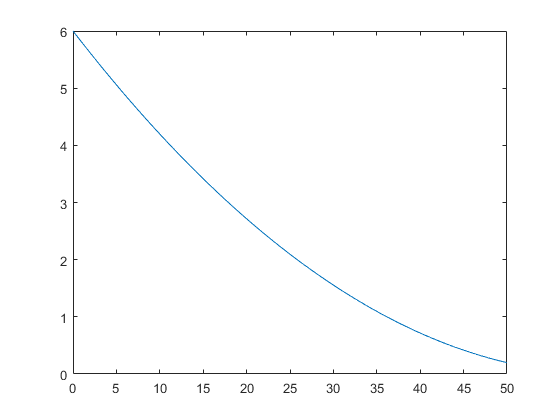

plot(x,y);

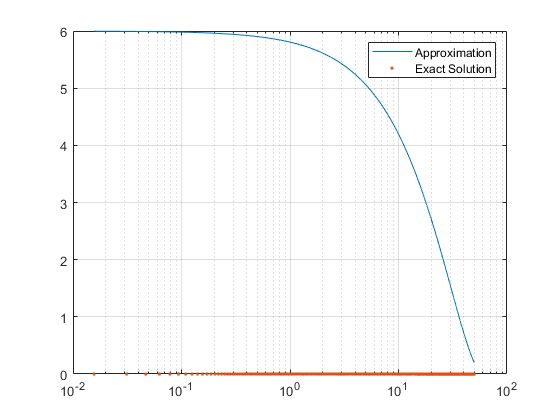

semilogx(x,y,x,q, ".");
legend('Approximation','Exact Solution')
grid on